# s_oeBloodFluorophoreTongueSrch 

The notes are in s_oeBloodFluorophoreLipSrch.mlx.

From 500-600n, there is an excellent fit with the {'collagen1','KeratinPalero','FADLin'} fluorophores.  The deviation is mainly with the 450nm excitation light.  We think there was some light leaking through.  Joyce actually knows.  When we do the fits from 520-600 nm, even the 450 nm excitation light nails the data perfectly.

## Initialize

Different analyses are based on different wavebands.

ieInit;
wave = 510:700;
normWave = 520;
yscale = 'linear';
odLevels = 1:1:40;
[T,dataDir] = oeDatabaseCreate;

## Create fluorophore matrix and read database 

**Our winners so far**

- fluorophoreNames = {'collagen1-smooth','KeratinPalero','FADLin','PorphyrinBjurshammar','chlorophyllA-7'}

We should also try deoxygenated blood at some point, by adding in a collagen-deoxy column.

fluorophoreNamesB = ...
    {'collagen1-smooth','KeratinPalero','FADLin','PorphyrinBjurshammar','chlorophyllA-7'};
[fluorophoresB,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## 405/415 nm excitation

subjects = {'Z','B','D','J'};

% Here is oxy
% https://omlc.org/spectra/hemoglobin/summary.html
oxyblood = medium('oxy_molarExtinctionCoefficient.mat','wave',wave);
odError = zeros(numel(odLevels),numel(subjects));  
ods = zeros(numel(subjects),1);    
rmse = zeros(size(subjects));

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405,'e level',980);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415,'e level',910);
    tongueFiles = cat(1,files405,files415);

    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);    
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 20.00
OD across subjects for 405/415nm 18.00
OD across subjects for 405/415nm 17.00
OD across subjects for 405/415nm 23.00


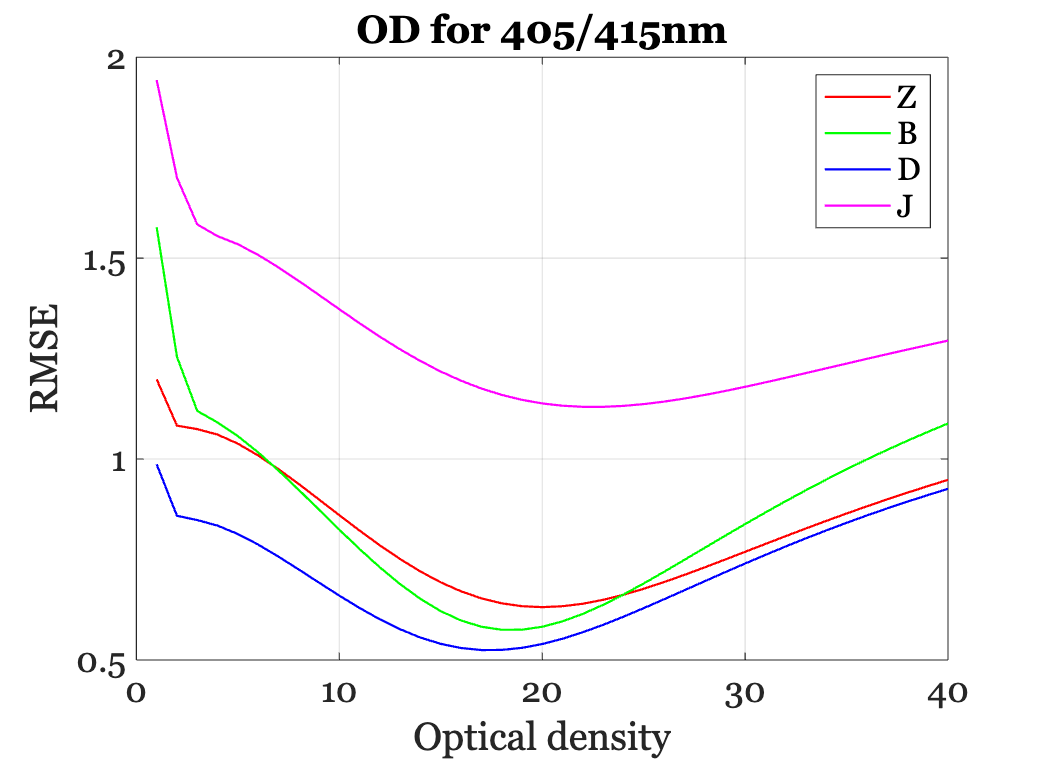


% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 405/415nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## Apply the proper optical density and plot

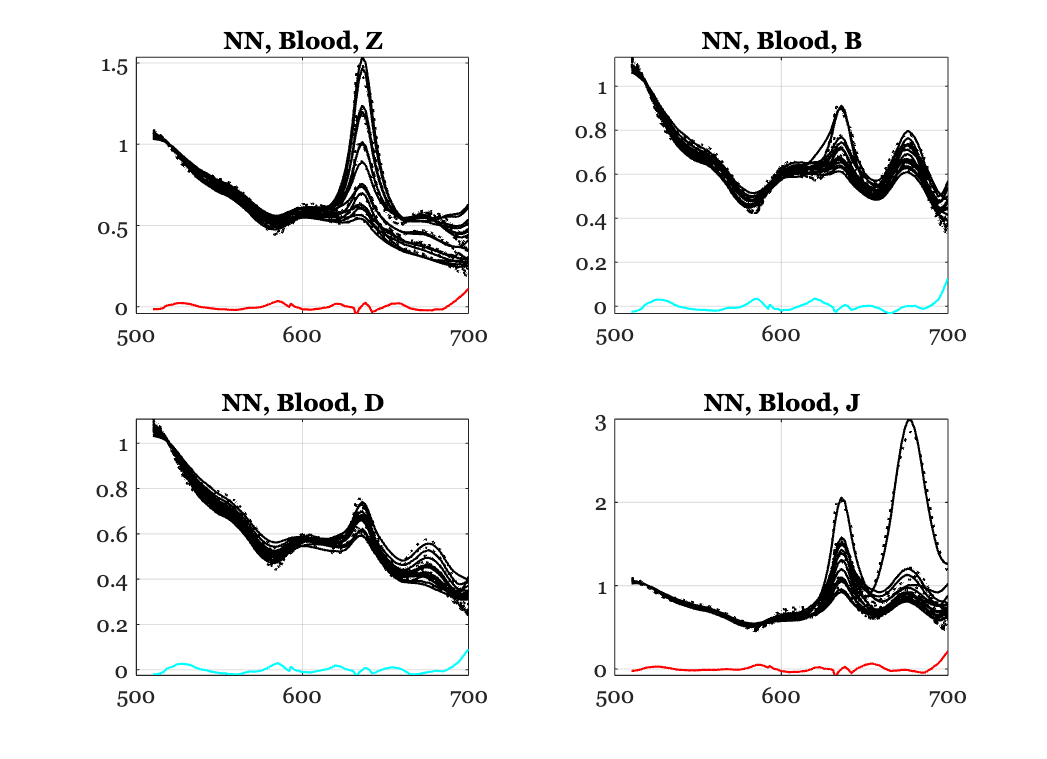

Subject Z
   11.0680   11.1645   10.9838   11.4384   10.4787   10.3916   10.4446   10.7176   10.0193    9.8373   11.2464   11.8841    8.9486    9.0810    9.0800
    0.8057    0.7889    0.7689    0.8226    0.6859    0.7325    0.6891    0.7636    0.7205    0.7347    0.6955    0.8370    0.7861    0.7806    0.7793
    0.4621    0.4752    0.4927    0.4438    0.5507    0.5198    0.5504    0.4962    0.5322    0.5237    0.5366    0.4299    0.4958    0.4971    0.4975
    0.1630    0.1407    0.2653    0.0951    0.6788    0.7292    0.5002    0.5262    1.0200    0.9575    0.3846    0.2789    0.1612    0.2457    0.0928
    0.0728    0.0813    0.1389    0.0534    0.1828    0.2084    0.2231    0.2357    0.1823    0.2070    0.2340    0.1458    0.0324    0.0249    0.0352

Subject B
   14.3586   12.5847   13.1626   16.1468   14.8598   15.0366   14.2303   15.5893   14.4991   14.7559   13.9765   12.9264   11.7388   12.8611
    0.7371    0.7032    0.7158    0.7602    0.7701    0.7849    0.7994    0.7602   

ieFigure;
tiledlayout(2,2);

deoxyblood = medium('deoxy_molarExtinctionCoefficient.mat','wave',wave);
deoxyblood.opticalDensity = 5;

for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','tongue','e wave',415);
    tongueFiles = cat(1,files405,files415);
    tongueData = oeReadFiles(tongueFiles,'normalized wave',normWave,'wave',wave);

    oxyblood.opticalDensity = ods(ii);
    [fluorophores, fluorophoreNames]  = oeApplyBlood(fluorophoresB,fluorophoreNamesB,...
        oxyblood);
    wgtsNN = zeros(size(fluorophores,2),size(tongueData,2));

    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end
    residual = tongueData - fluorophores*wgtsNN;
    rmse(ii) = norm(residual(:),2);

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:', ...
        wave,mean(residual,2));
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end

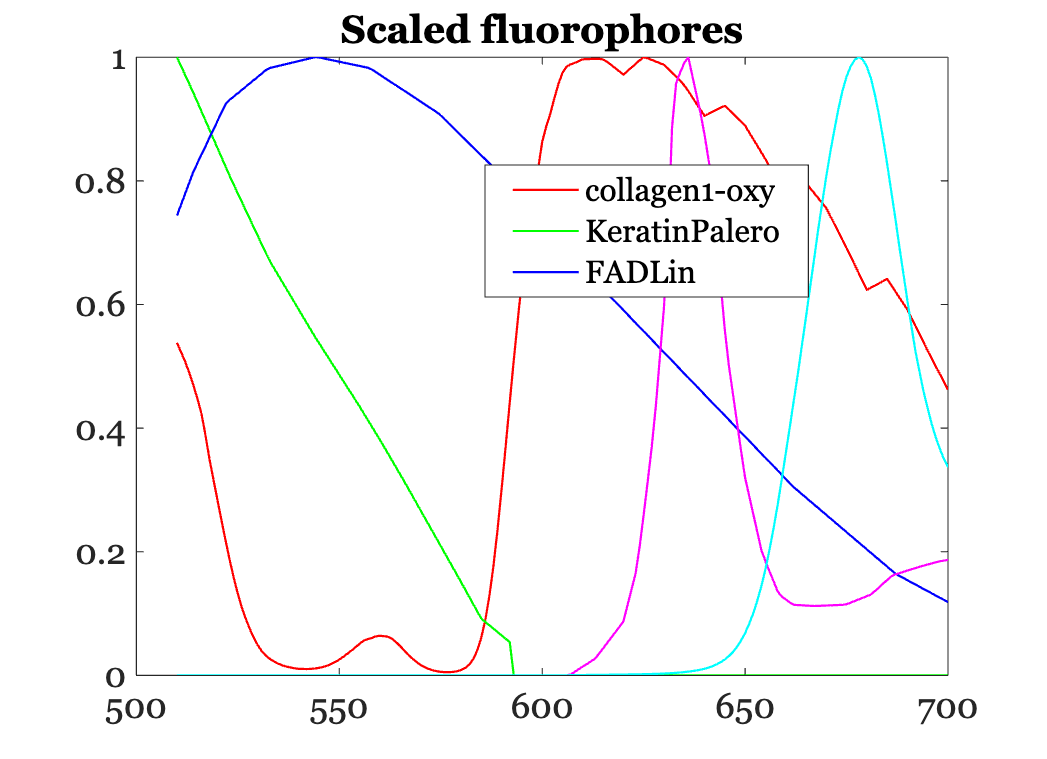


ieFigure; 
mx = max(fluorophores);
plot(wave,fluorophores*diag(1./mx));
title('Scaled fluorophores');
legend(fluorophoreNames);

legend(["collagen1-oxy", "KeratinPalero", "FADLin"], "Position", [0.4630 0.6080 0.3095, 0.1743])


disp(rmse); 

    1.3500    1.2517    0.9911    2.3610



## Create 450 nm blood optical density levels

odError = zeros(numel(odLevels),numel(subjects));

for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},...
        'substrate','tongue',...
        'e wave',450);
    tongueData = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);
    [ods(ii),odError(:,ii)] = oeBloodEstimateOD(fluorophoresB,fluorophoreNamesB,tongueData,wave,odLevels);
end
fprintf('OD across subjects for 405/415nm %.2f\n',ods);

OD across subjects for 405/415nm 20.00
OD across subjects for 405/415nm 22.00
OD across subjects for 405/415nm 19.00
OD across subjects for 405/415nm 20.00


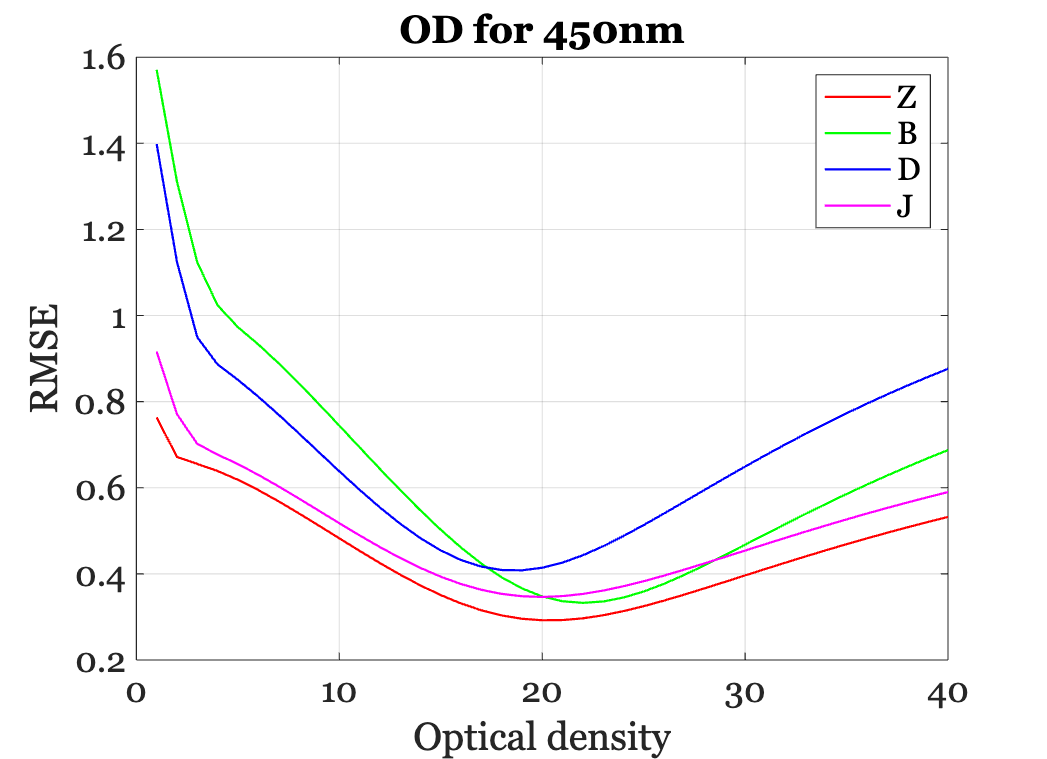



% These are the optical density levels to use for each of the subjects
ieFigure;
plot(odLevels,odError); hold on;
grid on; title('OD for 450nm');
legend(subjects);
xlabel('Optical density'); ylabel('RMSE');

## 450 nm excitation light

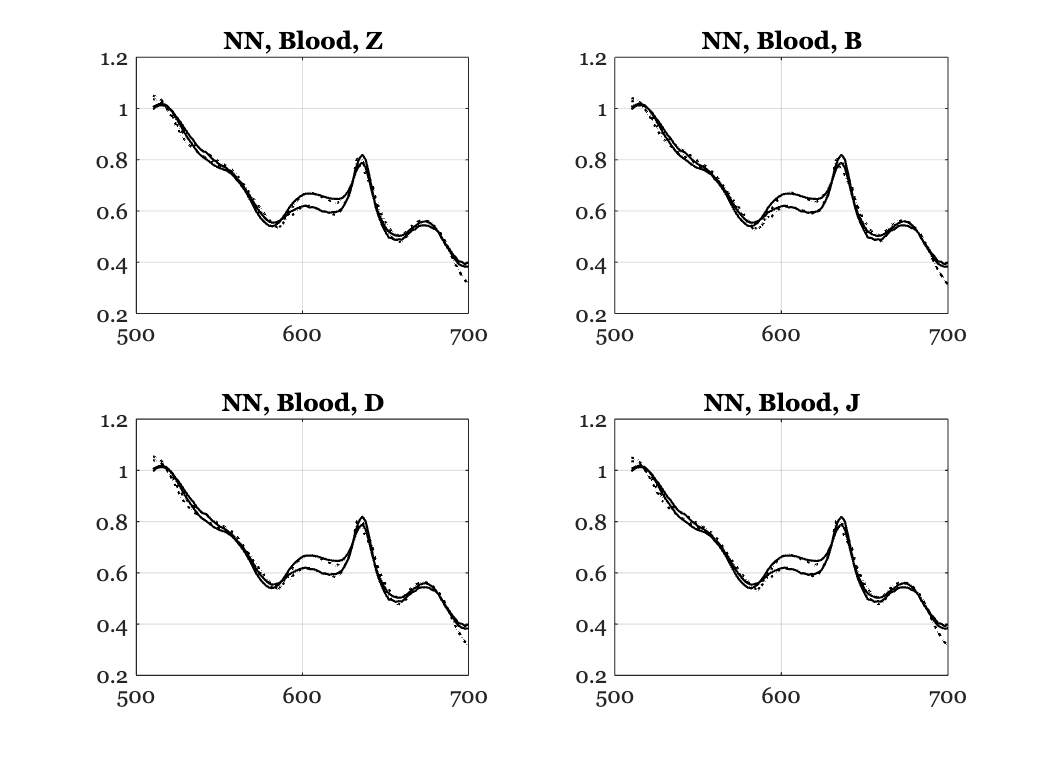

Subject Z
   12.2527    9.7227
    0.6371    0.6667
    0.5531    0.5630
    0.2292    0.3106
    0.2150    0.2441

Subject B
   12.6201   10.0135
    0.6671    0.6905
    0.5501    0.5606
    0.2213    0.3044
    0.2102    0.2403

Subject D
   12.0540    9.5653
    0.6199    0.6531
    0.5549    0.5644
    0.2335    0.3140
    0.2177    0.2462

Subject J
   12.2527    9.7227
    0.6371    0.6667
    0.5531    0.5630
    0.2292    0.3106
    0.2150    0.2441



ieFigure;
tiledlayout(2,2);
for ii=1:numel(subjects)
    wgtsNN = zeros(size(fluorophoresB,2),size(tongueData,2));

    oxyblood.opticalDensity = ods(ii);
    fluorophores = oeApplyBlood(fluorophoresB,fluorophoreNamesB,oxyblood);
    for dd = 1:size(tongueData,2)
        wgtsNN(:,dd) = lsqnonneg(fluorophores,tongueData(:,dd));
    end

    nexttile
    plot(wave,tongueData,'k-',wave,fluorophores*wgtsNN,'k:');
    grid on; title(sprintf('NN, Blood, %s',subjects{ii}));
    fprintf('Subject %s\n',subjects{ii}); disp(wgtsNN);
end